# Convex Optimization

## Mohammadreza Arani

## 810100511

% Hw8-Q1:
clear;
clc;
close all;
% Load Data:
run('spacecraft_landing_data.m');

## Optimize using CVX_MATLAB:

%%% Part (a):
cvx_begin
        variables p(3,K+1) v(3,K+1) f(3,K)

        v(:,2:K+1) == v(:,1:K) + 1/m*h*f - h * g * repmat([0;0;1],1,K);

        p(:,2:K+1) == p(:,1:K)+(h/2)*(v(:,1:K)+v(:,2:K+1));
        p(:,1) == p0;
        p(:,K+1) == 0;
        v(:,K+1) == 0;
        v(:,1) == v0; 
        p(3,:)   >= alpha*norms(p(1:2,:));
        norms(f) <= Fmax;
        
        minimize(sum(norms(f)))

cvx_end

 
Calling SDPT3 4.0: 507 variables, 302 equality constraints
------------------------------------------------------------

 num. of constraints = 302
 dim. of socp   var  = 388,   num. of socp blk  = 106
 dim. of linear var  = 71
 dim. of free   var  = 48 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|1.4e+02|9.0e+07| 4.713333e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.059|0.020|1.7e+01|1.3e+02|1.9e+07| 3.170669e+04 -5.811568e+03| 0:0:00| chol  1  1 
 2|0.284|0.807|1.2e+01|2.6e+01|1.5e+06| 3.654045e+04 -2.540090e+04| 0:0:00| chol  1  1 
 3|0.907|0.940|1.1e+00|1.7e+00|1.2e+05| 1.64

thrust_force  = cvx_optval;
min_fuel = thrust_force *gamma*h;

p_minf = p; v_minf = v; f_minf = f;

% Display Answers:
sprintf("minimum fuel value : %.2f",min_fuel)

ans = "minimum fuel value : 192.99"

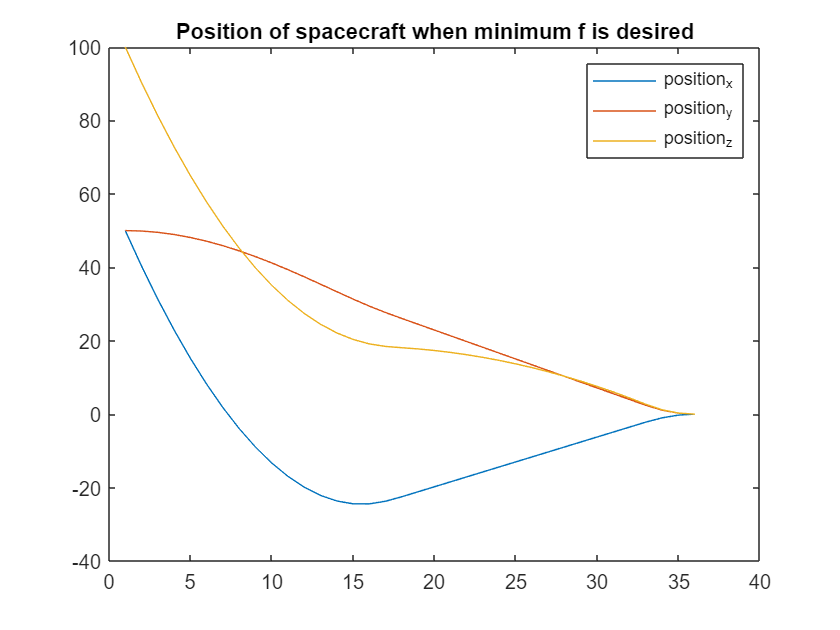

figure()
plot(1:length(p(1,:)),p);
title('Position of spacecraft when minimum f is desired')
legend('position_x','position_y','position_z')

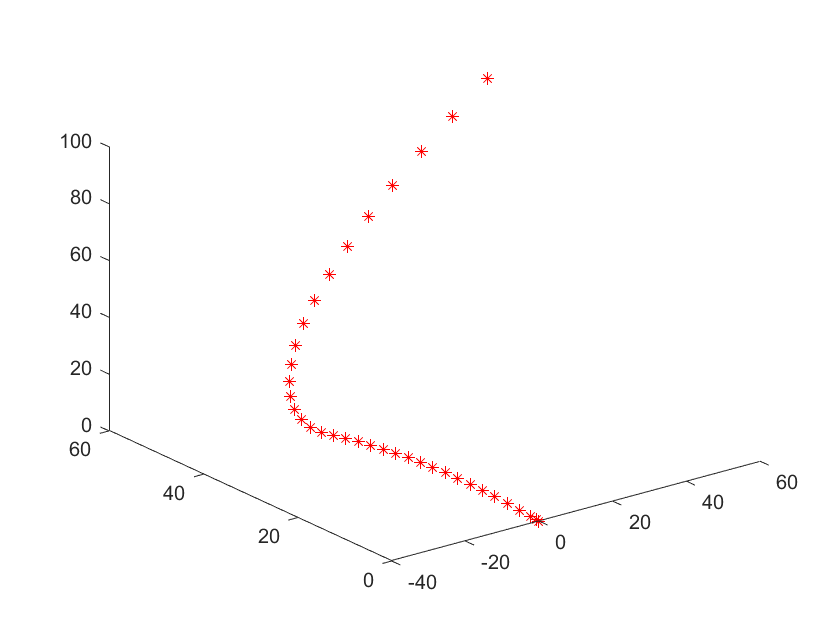

% Trajectory:
Fig1=figure();
for i=1:length(p(1,:))
  plot3(p(1,i),p(2,i),p(3,i),'*r');
  hold on;
  pause(0.1);
end

## Part (b)

% Find Min K
Ki = K;

while(1)
    cvx_begin
            variables p(3,Ki+1) v(3,Ki+1) f(3,Ki)
            % Constraints:
            v(:,2:Ki+1) == v(:,1:Ki)+(h/m)*f-h*g*repmat([0;0;1],1,Ki)
            p(:,2:Ki+1) == p(:,1:Ki)+(h/2)*(v(:,1:Ki)+v(:,2:Ki+1));
            p(:,1) == p0; v(:,1) == v0;
            p(:,Ki+1) == 0; v(:,Ki+1) == 0;
            p(3,:) >= alpha*norms(p(1:2,:));
            norms(f) <= Fmax;     

    minimize(sum(norms(f))) % The Objective

    cvx_end
    if(strcmp(cvx_status,'Infeasible') == 1)
        Kmin = Ki+1; % we find out this K is not feasible and previous K was the minimum!
        break;
    end
    Ki = Ki-1; % Reduce K until it is not feasible!
    p_mink = p; v_mink = v; f_mink = f;
end

 
Calling SDPT3 4.0: 507 variables, 302 equality constraints
------------------------------------------------------------

 num. of constraints = 302
 dim. of socp   var  = 388,   num. of socp blk  = 106
 dim. of linear var  = 71
 dim. of free   var  = 48 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|1.4e+02|9.0e+07| 4.713333e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.059|0.020|1.7e+01|1.3e+02|1.9e+07| 3.170669e+04 -5.811568e+03| 0:0:00| chol  1  1 
 2|0.284|0.807|1.2e+01|2.6e+01|1.5e+06| 3.654045e+04 -2.540090e+04| 0:0:00| chol  1  1 
 3|0.907|0.940|1.1e+00|1.7e+00|1.2e+05| 1.64

## Glide Cone:

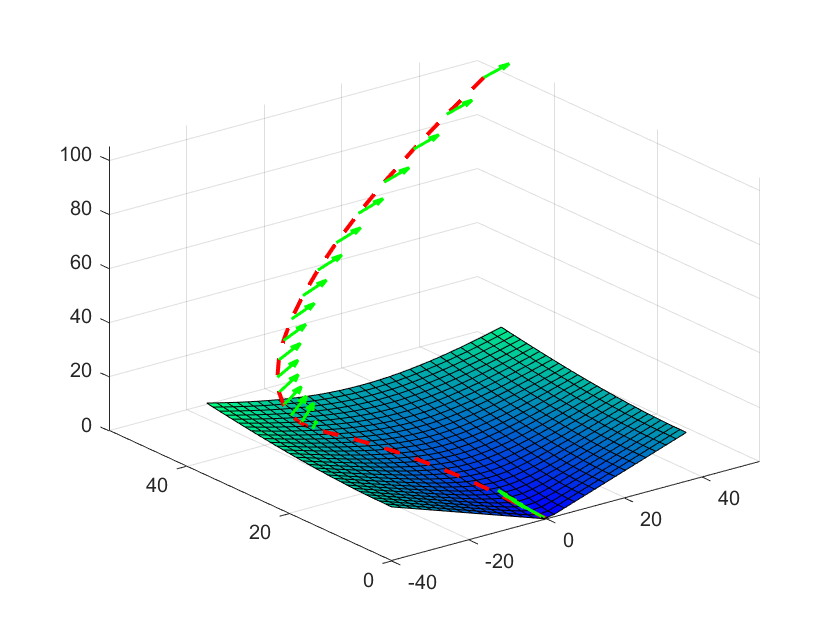

x = linspace(-40,length(p_minf),30); 
y = linspace(0,length(p_minf),30); 
[X,Y] = meshgrid(x,y); % Create a Surface from Axis x  and  y
Z = alpha*sqrt(X.^2+Y.^2); % Value oin the 3rd dimension

Fig3=figure();
colormap winter; 
surf(X,Y,Z);
axis([-40,55,0,55,0,105]);
grid on; 
hold on;
plot3(p_minf(1,:),p_minf(2,:),p_minf(3,:),'r--','linewidth',2);
quiver3(p_minf(1,1:K),p_minf(2,1:K),p_minf(3,1:K),...
                    f_minf(1,:),f_minf(2,:),f_minf(3,:),0.3,'g','linewidth',1.5);

title('Part a space craft trajectory');


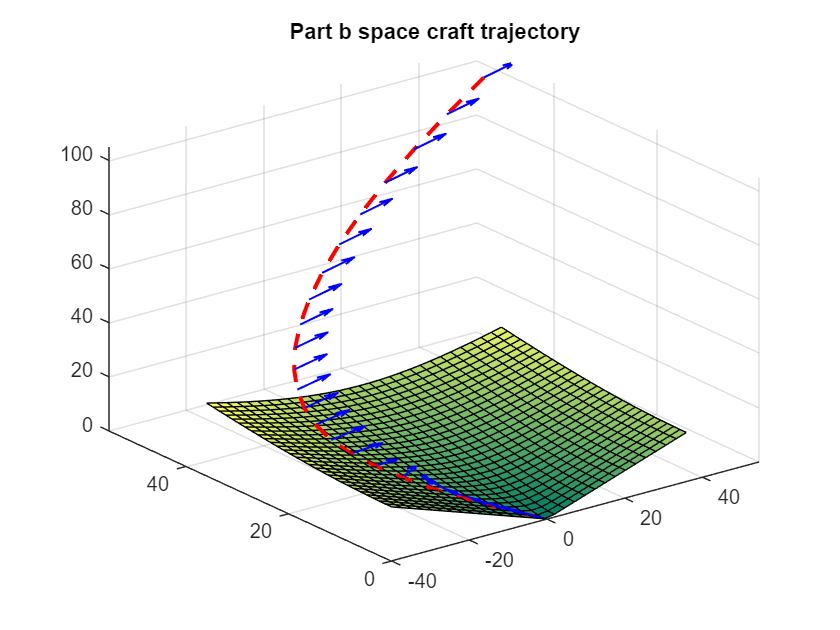

% plot minimum time trajectory for part (b)
Fig4=figure(); 
colormap summer; 
surf(X,Y,Z);
axis([-40,55,0,55,0,105]);
grid on;
hold on;
plot3(p_mink(1,:),p_mink(2,:),p_mink(3,:),'r--','linewidth',2);
quiver3(p_mink(1,1:Kmin),p_mink(2,1:Kmin),p_mink(3,1:Kmin),...
                        f_mink(1,:),f_mink(2,:),f_mink(3,:),0.3,'b','linewidth',1);
title('Part b space craft trajectory');

% Reporting minimum touch down Time --From part b ---:
disp(Ki) % Disp K

    24



disp(Ki*h)% for h = 1 --> T = K;

    24

